# HW - Ch 19 & 20, Numerical Integration

## Problem 1

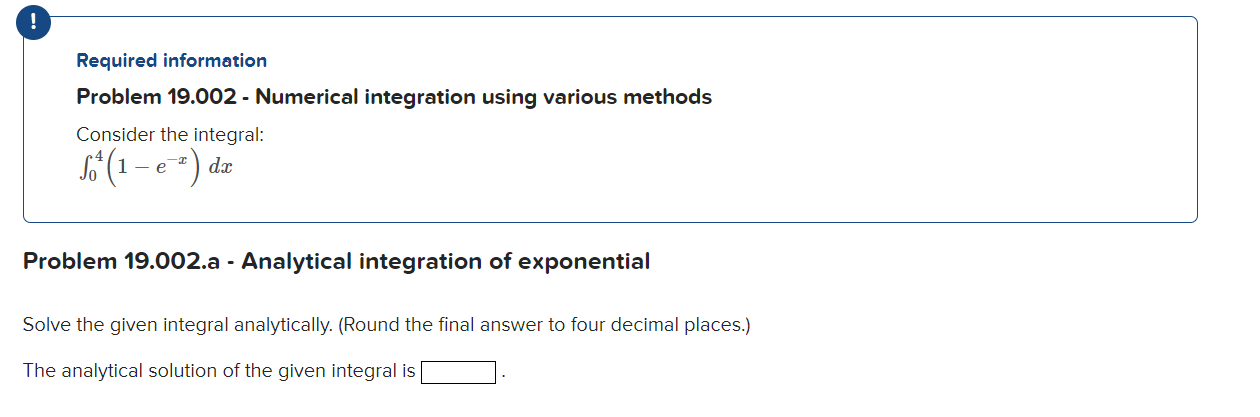

% F = x + exp(x) | 0 to 4
%    4 + exp(-4) - (0+exp(0))
%    3 + exp(-4)
analyt = 3 + exp(-4)

analyt = 3.0183


% integral
help integral

 integral  Numerically evaluate integral.
    Q = integral(FUN,A,B) approximates the integral of function FUN from A
    to B using global adaptive quadrature and default error tolerances.
 
    FUN must be a function handle. A and B can be -Inf or Inf. If both are
    finite, they can be complex. If at least one is complex, integral
    approximates the path integral from A to B over a straight line path.
 
    For scalar-valued problems the function Y = FUN(X) must accept a vector
    argument X and return a vector result Y, the integrand function
    evaluated at each element of X. For array-valued problems (see the
    'ArrayValued' option below) FUN must accept a scalar and return an
    array of values.
 
    Q = integral(FUN,A,B,PARAM1,VAL1,PARAM2,VAL2,...) performs the
    integration with specified values of optional parameters. The available
    parameters are
 
    'AbsTol', absolute error tolerance
    'Rel

FUN = @(x) 1 - exp(-x); A = 0; B = 4;
Q = integral(FUN,A,B)

Q = 3.0183


% romberg
help romberg

  romberg: Romberg integration quadrature
  [q,ea,iter] = romberg(func,a,b,es,maxit)
  Romberg integration.
  input:
  func = name of function to be integrated
  a, b = integration limits
  es = desired relative error (default = 0.000001%)
  maxit = maximum allowable iterations (default = 30)
  p1,p2,... = additional parameters used by func
  output:
  q = integral estimate
  ea = approximate relative error (%)
  iter = number of iterations



[q,ea,iter] = romberg(FUN,A,B)

q = 3.0183

ea = 4.1457e-10

iter = 5

## Prob 2

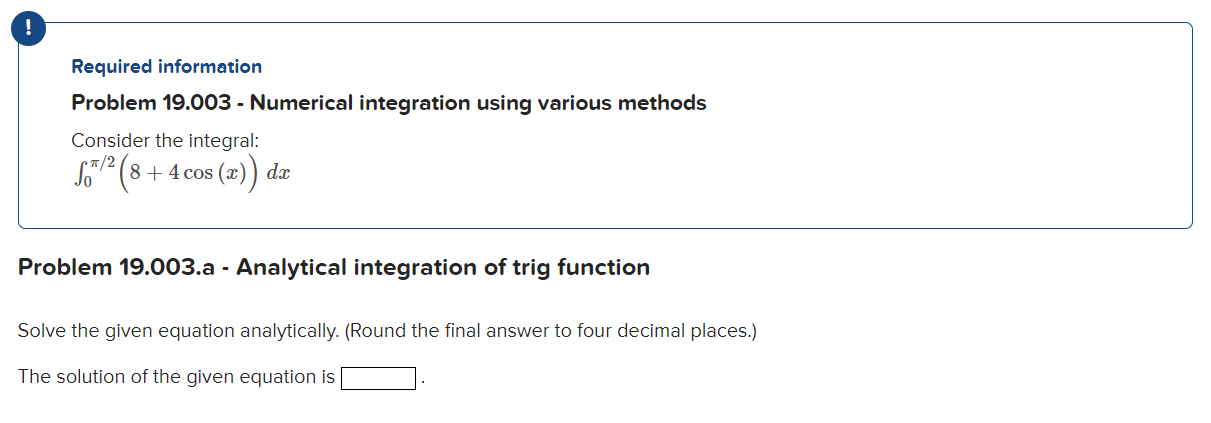

% 8x - 4*sin(x) | 0 to pi/2
analyt2 = (8*pi/2 + 4*sin(pi/2)) - (0+4*sin(0))

analyt2 = 16.5664


% integral
f = @(x) 8 + 4*cos(x); a = 0; b = pi/2;
int = integral(f,a,b)

int = 16.5664

## Prob 3

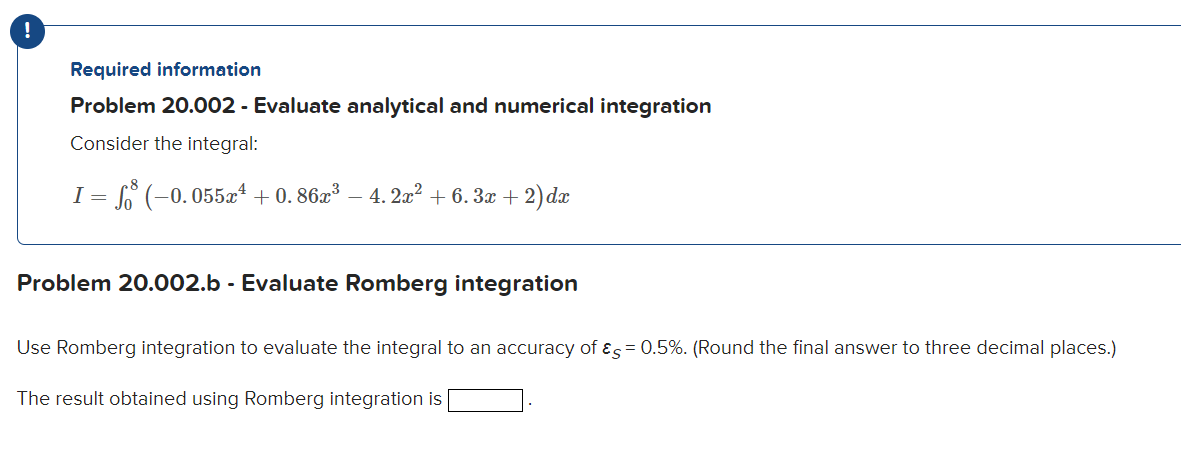

% analytical
F = @(x) -0.011*x.^5 + 0.86/4*x.^4 - 4.2/3*x.^3 + 6.3/2*x.^2 + 2*x;
interv = F(8) - F(0)

interv = 20.9920


% romberg
f = @(x) -0.055*x.^4 + 0.86*x.^3 - 4.2*x.^2 + 6.3*x + 2;
a = 0; b = 8; es = 0.5;
[q,ea,iter] = romberg(f,a,b,es)

q = 20.9920

ea = 0

iter = 3



% integral
qI = integral(f,a,b)

qI = 20.9920

## Prob 6

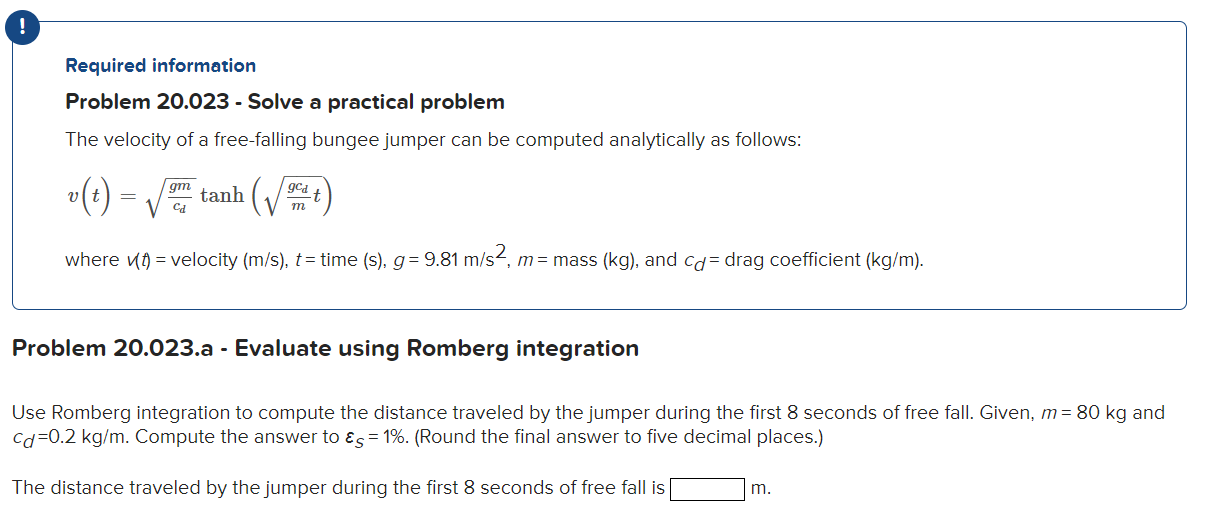

## Prob 7

g = 9.81; m = 80; Cd = 0.2;
a = 0; b = 8; n = 10000; tol = 1;
v = @(t) sqrt(g*m/Cd)*tanh(sqrt(g*Cd/m)*t);

format long
d = integral(v,a,b)

d =      2.552600300762053e+02


d_relTol = integral(v, a, b, 'RelTol', 0.01)

d_relTol =      2.552600300762053e+02


d_romb = romberg(v,a,b,es)

d_romb =      2.552416630588677e+02


## Prob 7